clear all
[sig fs] = audioread('guitar.wav');
[sig2 fs] = audioread("bass.wav");
[sig3 fs] = audioread("two_drums_new.wav");
[sig4 fs] = audioread("bgs.wav");

fixedSig1 = sig(1:4593084)

fixedSig1 =    -0.0061
   -0.0081
   -0.0090
   -0.0098
   -0.0097
   -0.0075
   -0.0051
   -0.0050
   -0.0061
   -0.0050


fixedSig2 = sig2(1:4593084) 

fixedSig2 =    -0.0027
   -0.0028
   -0.0031
   -0.0032
   -0.0031
   -0.0034
   -0.0036
   -0.0038
   -0.0040
   -0.0043


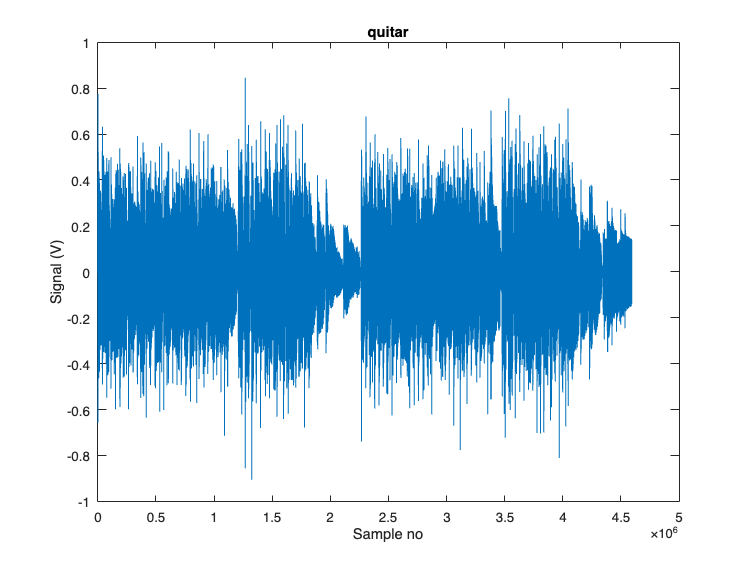


sound(fixedSig1 + fixedSig2, fs)

combinedSig = fixedSig1 + fixedSig2;

figure(1);
clf;
plot(combinedSig);
xlabel('Sample no');
ylabel('Signal (V)');
title('quitar');

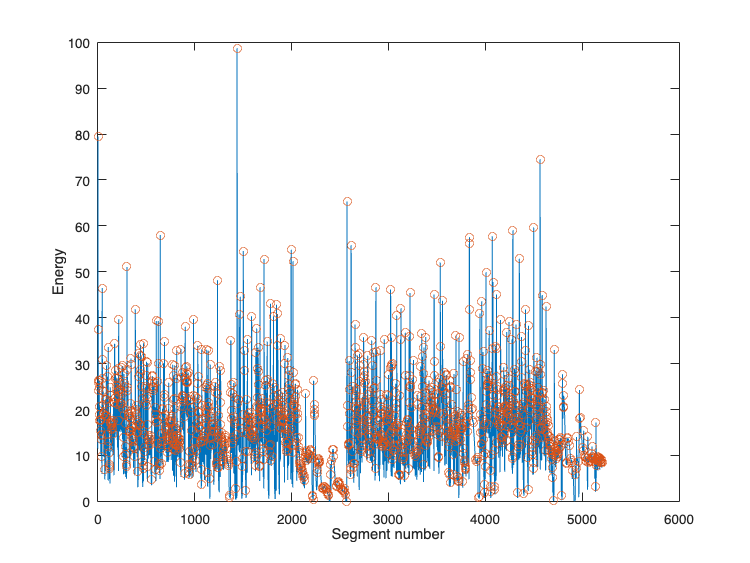


% Divide signal into segments and find its energy
T = 0.02;                  % Duration of each segment (20ms)
N = fs * T;                % Number of samples per segment
E = [];                    % Initialize an empty array to store energy values

for i = 1:N:length(combinedSig)-N+1
    seg = combinedSig(i:i+N-1);    % Extract segment from signal
    E = [E seg' * seg];    % Calculate and store energy of the segment
end


% Plot the energy graph and the peak values
figure(2);
clf;
x = 1:length(E);           % Segment indices
plot(x, E);                % Plot energy of each segment
xlabel('Segment number');  % Label for x-axis
ylabel('Energy');          % Label for y-axis
hold on;

% Find local maxima
[pks, locs] = findpeaks(E); % Find peaks and their locations
plot(locs, pks, 'o');       % Highlight peaks on the energy graph
hold off;

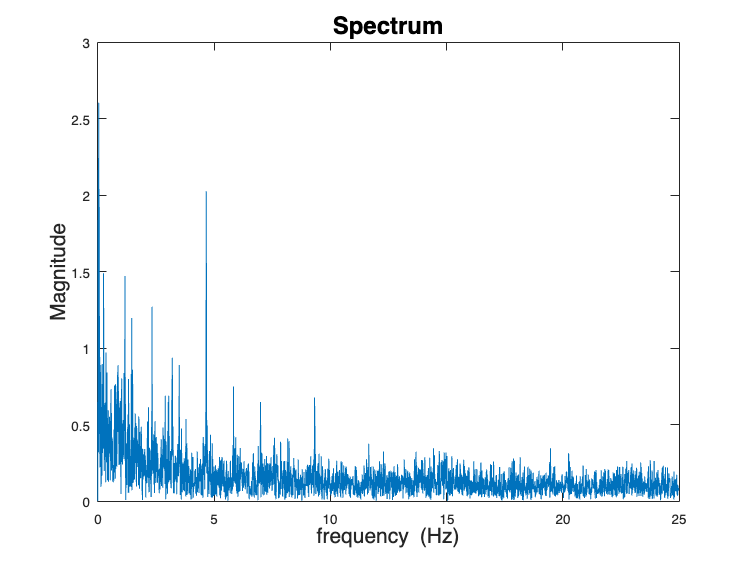


% Plot spectrum of energy
figure(3);
plot_spec(E - mean(E), 1/T); % Plot the energy spectrum (frequency domain)